# Part B

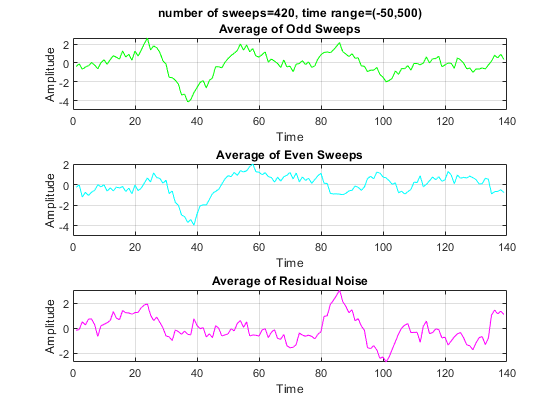

% Loading Data
data = load("ex2data.mat");
EEG = transpose(data.eeg);
INDF = data.indf;
INDD = data.indd;

figure(1)
[~, ~, ~, SNR1] = SNR_func(EEG, INDF , 420, -50, 500);

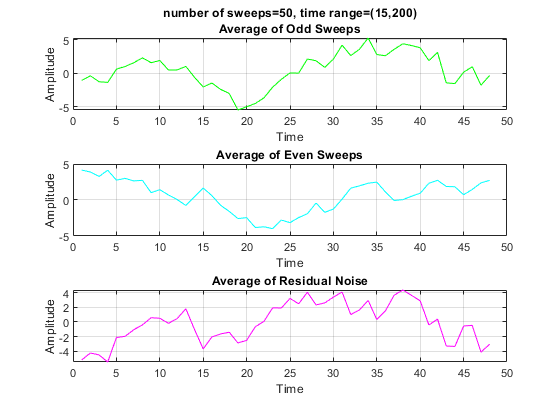


figure(2)
[~, ~, ~, SNR2] = SNR_func(EEG, INDF, 50, 15, 200);

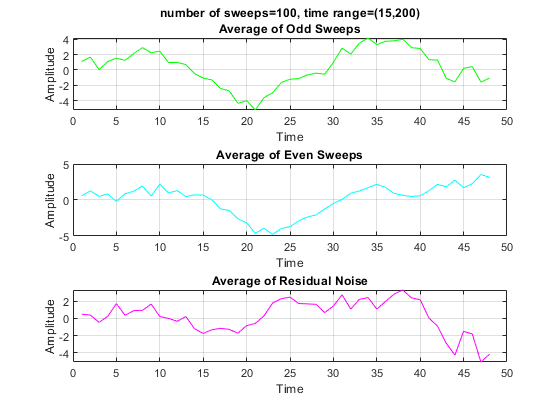


figure(3)
[~, ~, ~, SNR3] = SNR_func(EEG, INDF, 100, 15, 200);

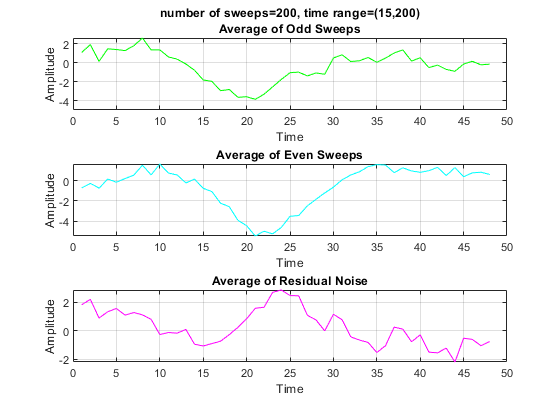


figure(4)
[~, ~, ~, SNR4] = SNR_func(EEG, INDF, 200, 15, 200);

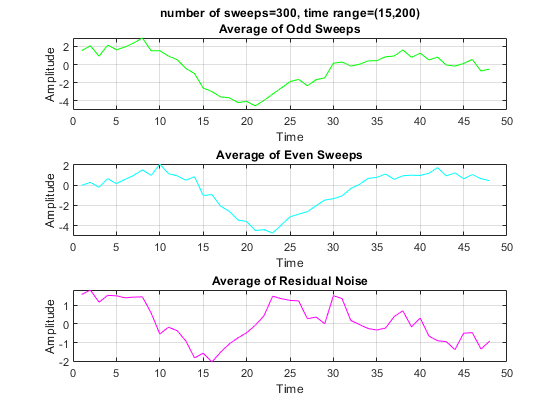


figure(5)
[~, ~, ~, SNR5] = SNR_func(EEG, INDF,  300, 15, 200);

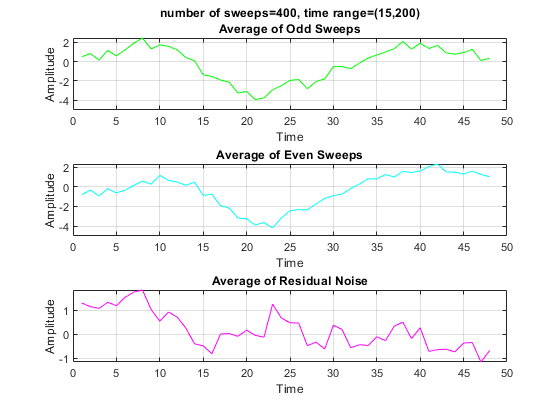


figure(6)
[~, ~, ~, SNR6] = SNR_func(EEG, INDF,  400, 15, 200);

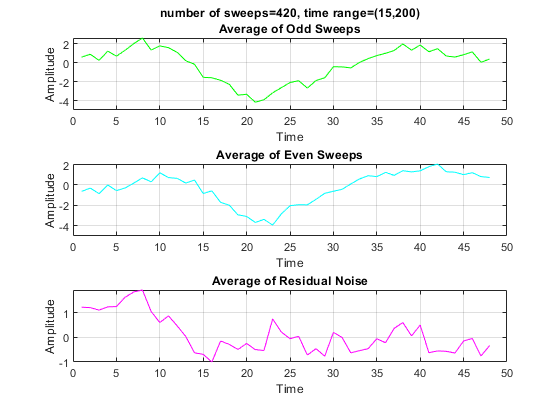


figure(7)
[~, ~, ~, SNR7] = SNR_func(EEG, INDF,  420, 15, 200);


% Plotting SNR vs number of Sweeps
figure(8)
SNRs = sprintf(['SNR1 = %G,\nSNR2 = %G,' ...
         '\nSNR3 = %G,\nSNR4 = %G,' ...
         ' \nSNR5 = %G,\nSNR6 = %G, \nSNR7 = %G   '], ...
         SNR1,SNR2,SNR3,SNR4, SNR5, SNR6, SNR7)

SNRs =     'SNR1 = 0.942734,
     SNR2 = 0.528181,
     SNR3 = 1.07527,
     SNR4 = 1.88382, 
     SNR5 = 3.09912,
     SNR6 = 4.94224, 
     SNR7 = 4.52623   '


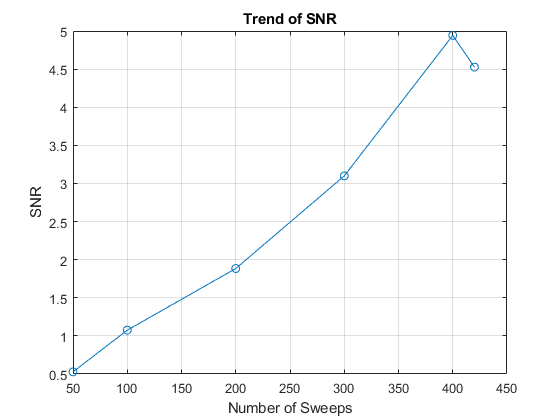

     
SNR = [SNR2 SNR3 SNR4 SNR5 SNR6 SNR7];
number_of_sweeps = [50 100 200 300 400 420];
plot(number_of_sweeps, SNR, 'marker', 'o')
title('Trend of SNR')
xlabel('Number of Sweeps')
ylabel('SNR')
grid on 